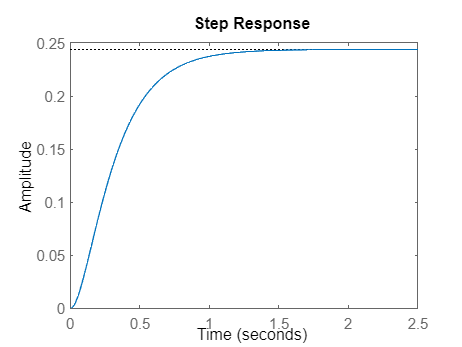

clear all
clc

% This file considers the velocity control problem 
% to guarantee that the rotor and the unknown load rotate at steady state at a given angular velocity
% Student Name: Giuditta Sigona
% Created on 21/03/2022
% Last version xx/yy/zz


% matlab colors
NMatlabRed      = [0.8500   0.3250   0.0980];
NMatlabYellow   = [0.929    0.694    0.125 ];
NMatlabBlue     = [0        0.4470   0.7410];  
NMatlabViolet   = [0.4940   0.1840   0.5560];
NMatlabGreen    = [0.4660   0.6740   0.1880];
NMatlabCyan     = [0.3010   0.7450   0.9330];
NMatlabBordeaux = [0.6350   0.0780   0.1840]; 

s = tf('s');
om = logspace(-2,5,1000);
t = 0:0.001:10;

% Parameters (MATLAB)
R = 2.0;                % Ohms
L = 0.5;                % Henrys
K = 0.1;               % torque constant
K = 0.1;               % back emf constant
b = 0.2;               % Nms
J = 0.02;               % kg.m^2/s^2

P1 = tf(K,[L R]);            % armature
P2 = tf(1,[J b]);            % eqn of motion

sys = ss(P2) * [P1 , 1];      % ref_w = h2 * (h1*Va + Td)
sys = feedback(sys,K,1,1);   % close back emf loop
stepplot(sys(1));

% sys = feedback(P1*P2,K);

% disturbed_sys = Td*feedback(P2,P1*K) % Disturbance (load torque) transfer function

t = 0:0.1:15;
Td = -0.1*(t>5 & t<10); % example load disturbance
u = [ones(size(t)) ; Td];       % ref=1 and Td


%******** only feedforward Kf *********
Kff = 1/dcgain(sys(1))

Kff = 4.1000


cl_Kf = sys * diag([Kff,1]);    % add feedforward gain
h1 = lsimplot(cl_Kf,u,t)


h1 =

	resppack.simplot



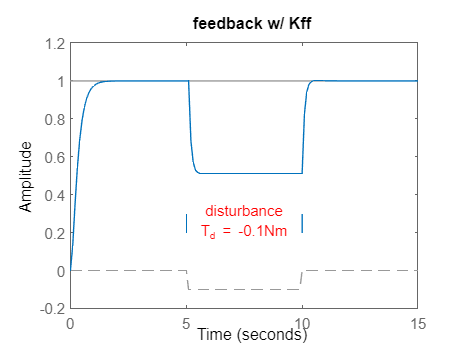

title('Setpoint tracking and disturbance rejection')
title('feedback w/ Kff')

% Annotate plot
line([5,5],[.2,.3]);
line([10,10],[.2,.3]);
text(7.5,.25,{'disturbance','T_d = -0.1Nm'},...
            'vertic','middle','horiz','center','color','r');


%************ pid controller ************
Cont = pidtune(feedback(P1*P2,K), 'PID')  % PI Controller  

Cont =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 8.62, Ki = 36.5, Kd = 0.509
 
Continuous-time PID controller in parallel form.



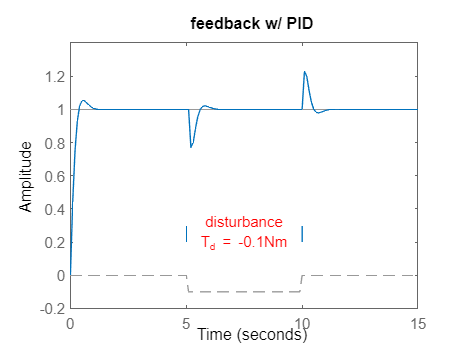


cl_Contr = feedback(sys * append(Cont,1),1,1,1);
h2 = lsimplot(cl_Contr,u,t);
title('Setpoint tracking and disturbance rejection')
title('feedback w/ PID')
% Annotate plot
line([5,5],[.2,.3]);
line([10,10],[.2,.3]);
text(7.5,.25,{'disturbance','T_d = -0.1Nm'},...
            'vertic','middle','horiz','center','color','r');


%********* H-inf ************
% ContH_num = (422.9*s^2 + 592*s + 4398);
% ContH_den = (s^3 + 205.9*s^2 + 2774*s + 165.7);
% ContH = ContH_num/ContH_den

ContH_num = (1.792*10^4*s^2 + 2.508*10^5*s + 7.346*10^5);
ContH_den = (s^3 + 610.5*s^2 + 4.367*10^4*s + 1222);
ContH = ContH_num/ContH_den

ContH =
 
   17920 s^2 + 250800 s + 734600
  --------------------------------
  s^3 + 610.5 s^2 + 43670 s + 1222
 
Continuous-time transfer function.



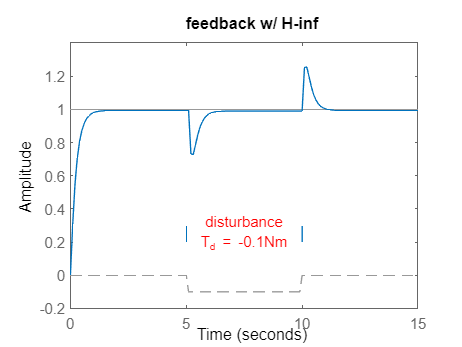


cl_CH = feedback(sys * append(ContH,1),1,1,1);
h3 = lsimplot(cl_CH,u,t);
title('Setpoint tracking and disturbance rejection')
title('feedback w/ H-inf')
% Annotate plot
line([5,5],[.2,.3]);
line([10,10],[.2,.3]);
text(7.5,.25,{'disturbance','T_d = -0.1Nm'},...
            'vertic','middle','horiz','center','color','r');

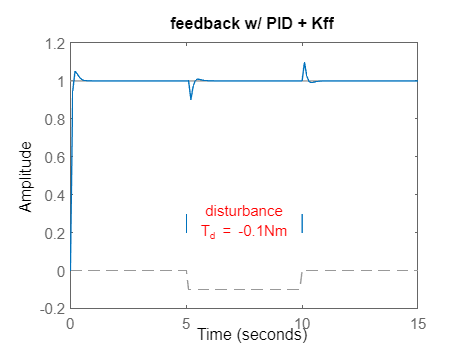


%********* PID + Kff ************

C = Cont*Kff;
cl_both = feedback(sys *append(C,1),1,1,1);
h4 = lsimplot(cl_both,u,t);
title('Setpoint tracking and disturbance rejection')
title('feedback w/ PID + Kff')
% Annotate plot
line([5,5],[.2,.3]);
line([10,10],[.2,.3]);
text(7.5,.25,{'disturbance','T_d = -0.1Nm'},...
            'vertic','middle','horiz','center','color','r');

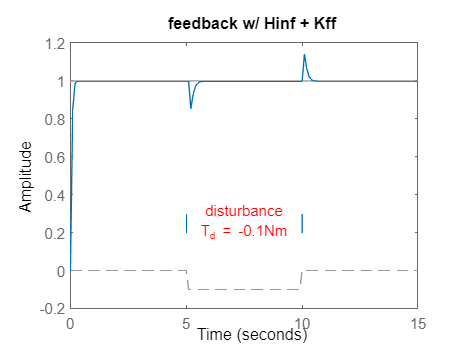


%********* Hinf + Kff ************

C = ContH*Kff;
cl_both2 = feedback(sys *append(C,1),1,1,1);
h5 = lsimplot(cl_both2,u,t);
title('Setpoint tracking and disturbance rejection')
title('feedback w/ Hinf + Kff')
% Annotate plot
line([5,5],[.2,.3]);
line([10,10],[.2,.3]);
text(7.5,.25,{'disturbance','T_d = -0.1Nm'},...
            'vertic','middle','horiz','center','color','r');

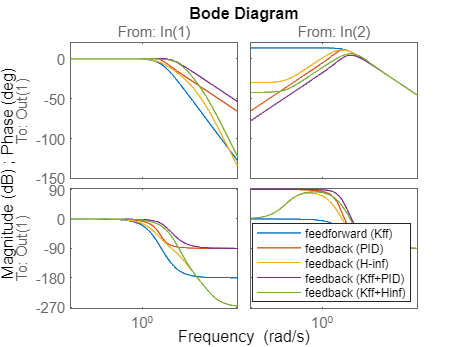


%This plot compares the closed-loop Bode diagrams
bode(cl_Kf,cl_Contr,cl_CH,cl_both,cl_both2)
legA = legend('feedforward (Kff)','feedback (PID)','feedback (H-inf)','feedback (Kff+PID)','feedback (Kff+Hinf)','Location','SouthEast');
set(legA,'FontSize',8)

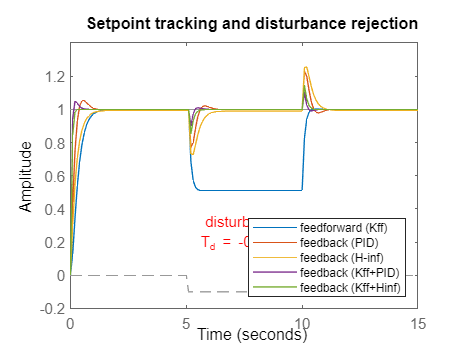


% compare the three DC motor control designs on disturbance rejecion tes
h = lsimplot(cl_Kf,cl_Contr,cl_CH,cl_both,cl_both2,u,t);
title('Setpoint tracking and disturbance rejection')
legA = legend('feedforward (Kff)','feedback (PID)','feedback (H-inf)','feedback (Kff+PID)','feedback (Kff+Hinf)','Location','SouthEast');
set(legA,'FontSize',8)

% Annotate plot
text(7.5,.25,{'disturbance','T_d = -0.1Nm'},...
            'vertic','middle','horiz','center','color','r');

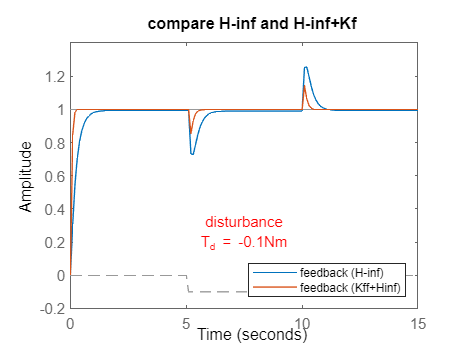



% compare H-inf and H-inf+Kf
h6 = lsimplot(cl_CH,cl_both2,u,t);
title('Setpoint tracking and disturbance rejection')
title('compare H-inf and H-inf+Kf')
legA = legend('feedback (H-inf)','feedback (Kff+Hinf)','Location','SouthEast');
set(legA,'FontSize',8)
% Annotate plot
text(7.5,.25,{'disturbance','T_d = -0.1Nm'},...
            'vertic','middle','horiz','center','color','r');